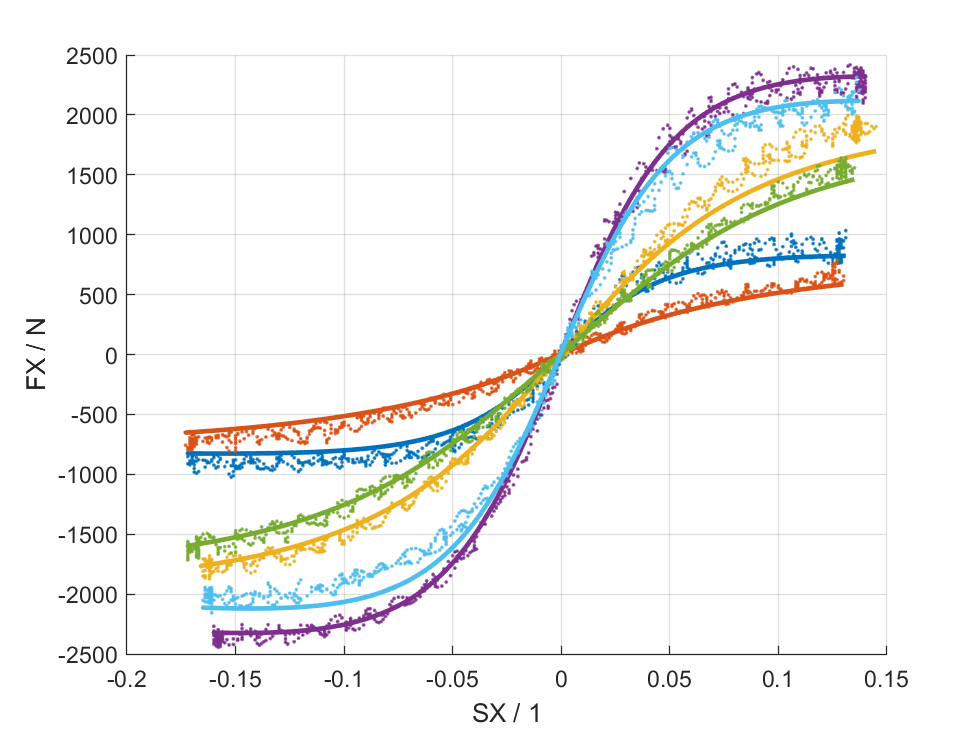

folder = fileparts(matlab.desktop.editor.getActiveFilename());
folder = fullfile(folder, 'fsae-ttc-data');
file = fullfile(folder, 'fsaettc_obfuscated.tir');
tyre = MagicFormulaTyre(file);

file = fullfile(folder, 'fsaettc_obscured_testbench_drivebrake.mat');
parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurements = parser.run(file);
measurements = measurements([30 40 55 60 70 75]);

figure(); grid on; hold on
c = colororder();
for i = 1:numel(measurements)
    [SX,SA,FZ,IP,IA,VX,FX] = unpack(measurements(i));
    FX_mdl = magicformula(tyre,SX,SA,FZ,IP,IA,VX);
    plot(SX, FX_mdl, 'Color', c(i,:), 'LineWidth', 2)
    plot(SX, FX, '.', 'Color', c(i,:), 'MarkerSize', 4)
end
xlabel('SX / 1'); ylabel('FX / N')